## Individual assignment I - Sing and analyse!

### **Generate Clean Sinusoidal Signal**.

clear;

% Setup parameters
fs = 10000;             % sampling frequency
T = 0.5;                % duration in seconds

% Frequency resolution
delta_f = 1 / T;        % frequency resolution (depends on duration)


% Frequency vectors for positive and negative frequencies
f_pos = 0:delta_f:fs/2;         % positive frequencies up to fs/2 (Nyquist)
f_neg = -fs/2+delta_f:delta_f:-delta_f;  % negative frequencies from -fs/2 to 0

% Function to generate a sinusoid
function [time_vector, signal] = generate_sinusoid(a, f, phi, fs, T_s)
    time_vector = 0:1/fs:T_s-1/fs;
    signal = a * cos(2 * pi * f * time_vector + phi);
end

% Generate a clean 1000 Hz sinusoid for comparison
[x_values, clean_signal] = generate_sinusoid(1, 1000, 0, fs, 0.5);  % 1000 Hz, amplitude 1


### **Analyze Voice Recording** and Compute the Spectrum.

% Load voice recording
[recorded_signal, fs_audio] = audioread('iiiiii.wav');

% Convert stereo to mono if necessary
if size(recorded_signal, 2) == 2
    recorded_signal = mean(recorded_signal, 2);  % Convert stereo to mono
end

% Use the last 24000 samples of the recorded signal for FFT
[Y_voice, freq_voice] = make_spectrum(recorded_signal(end-24000+1:end), fs);


### **Compare the Clean Signal and Recorded Signal using Stem Plot**.

% Call make_spectrum for the clean sinusoid
[Y_clean, freq_clean] = make_spectrum(clean_signal, fs);


FFT

% Truncate the signal to the last 24000 samples for analysis
recorded_signal = recorded_signal(end-24000+1:end);

% Number of samples in the truncated recorded signal
n_optaget = length(recorded_signal);

% Compute FFT for the recorded signal
optaget_fft = abs(fft(recorded_signal));

% Normalize FFT for correct scale
optaget_fft = optaget_fft / n_optaget;

% Only take the positive half of the FFT
optaget_fft = optaget_fft(1:floor(n_optaget/2));

% Define frequency axis for the recorded signal (using fs_audio)
f_optaget = (0:floor(n_optaget/2)-1)*(fs_audio/n_optaget);

% Find the dominant frequency in the recorded signal
[~, idx_max] = max(optaget_fft);
dominant_freq = f_optaget(idx_max);
% fprintf('The dominant frequency in the recorded signal is: %.2f Hz\n', dominant_freq);

% Compute the FFT for the clean signal
n_clean = length(clean_signal);
clean_fft = abs(fft(clean_signal));
clean_fft = clean_fft(1:floor(n_clean/2));
f_clean = (0:floor(n_clean/2)-1)*(fs/n_clean);

### **Plot the Decibel Magnitude Spectrum for Both Signals**.

**Stem Plot of Clean Sinusoid and Voice Signal**:

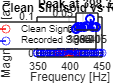

% Combined Stem Plot of Clean Sinusoid and Voice Signal
figure;

% Stem plot of clean sinusoid
stem(f_clean, abs(clean_fft), 'r', 'DisplayName', 'Clean Signal');
hold on;

% Stem plot of human voice signal
stem(f_optaget, abs(optaget_fft), 'b', 'DisplayName', 'Recorded Signal');

% Set axes limits and labels
xlim([350 450]);  % Adjust this limit to focus on the relevant part
ylim([-0.01 0.1]);  % Adjust as needed based on magnitude
xlabel('Frequency [Hz]');
ylabel('Magnitude [a.u.]');
title('Stem Plot: Clean Sinusoid vs Recorded Signal');
legend;
grid on;

% Zoomed-in inset for human voice peak at 398.35 Hz
zoom_x = [390 405];  % Adjust based on clean signal frequency
zoom_y = [0 0.05];   % Adjust based on the zoomed-in magnitude

% Create inset for zoomed-in view around 398 Hz
axes('Position', [0.67 0.65 0.2 0.2]);  % Adjust the position and size of inset
box on;
stem(f_optaget, abs(optaget_fft), 'b', 'LineWidth', 1.5);  % Zoomed-in stem plot for voice
xlim(zoom_x);
ylim(zoom_y);
title('Peak at 398.35 Hz');
grid on;

## **Plot the Decibel Magnitude Spectrum for Both Signals**.

### **Decibel Magnitude Plot for Both Signals**:

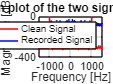

% Decibel magnitude plot of human voice and clean sinusoid for comparison
figure;

% Plot decibel magnitude of clean sinusoid
plot(freq_clean, 20*log10(abs(Y_clean)), 'r', 'DisplayName', 'Clean Signal');
hold on;

% Plot decibel magnitude of human voice
plot(freq_voice, 20*log10(abs(Y_voice)), 'b', 'DisplayName', 'Recorded Signal');

% Set axes limits and labels
xlim([-1500 1500]);
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('Spectrum plot of the two signals (dB scale)');
legend;
grid on;